% Define DH parameters for a 3-DoF robot (Run only once since the robot
% link is created and doesn't need to run again)
% in cm

L1 = Link([0 6.5 -1 pi/2 0]); % [theta d a alpha sigma]
L2 = Link([0 0 -10 0 0]);
L3 = Link([0 0 -14.6 0 0]);
L4 = Link([0 -1 0 -pi/2 0]);
L5 = Link([0 18.2 0 0 0]); 

% Special Note: Sigma is to identify whether the joint is revolute or prismatic
% revolute: sigma = 0
% prismatic: sigma = 1

% Apply theta offsets
L2.offset = 3*pi/2; % Offset for joint 2
L3.offset = 3*pi/2; % Offset for joint 3
L4.offset = 132*pi/180; % Offset for joint 4

% Create the robot model
robot = SerialLink([L1 L2 L3 L4 L5], 'name', '5-DoF Robot');


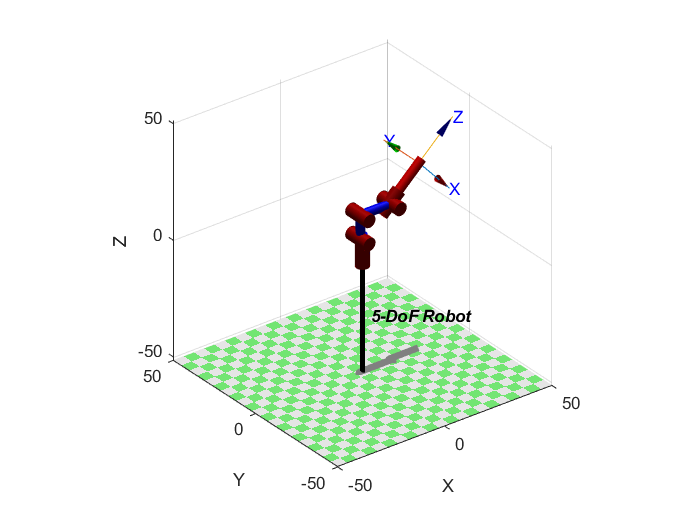

robot.plot([0 0 0 0 0]); % Specify initial joint angles (q1, q2, q3 in the relative order)

% Forward Kinematics
q = [0, 0, 0, 0, 0]; % Joint angles in radians (Joint angles must be in radians)
T = robot.fkine(q); % Compute the forward kinematics
disp(T); % Display the transformation matrix

       0.6691  4.55e-17    0.7431     27.13
    -4.55e-17         1-2.026e-17         1
      -0.7431-2.026e-17    0.6691     28.68
            0         0         0         1


robot.plot([0, 0, 0, 0, 0])

clc;
clear;

% Define symbolic variables for joint angles
syms theta1 theta2 theta3 theta4 theta5;

% D-H Parameters (a, alpha, d, theta)
DH = [
    0, pi/2, 6.5, theta1;                % T0,1
    -10, 0, 0, theta2 + 3*pi/2;         % T1,2
    -14.6, 0, 0, theta3 + 3*pi/2;       % T2,3
    0, -pi/2, -1, theta4 + 132*pi/180;  % T3,4
    0, 0, 18.2, theta5                  % T4,5
];

% Function to compute transformation matrix from D-H parameters
computeDH = @(a, alpha, d, theta) [
    cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
    sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0,           sin(alpha),             cos(alpha),            d;
    0,           0,                      0,                    1
];

% Calculate individual transformation matrices
T01 = computeDH(DH(1,1), DH(1,2), DH(1,3), DH(1,4));
T12 = computeDH(DH(2,1), DH(2,2), DH(2,3), DH(2,4));
T23 = computeDH(DH(3,1), DH(3,2), DH(3,3), DH(3,4));
T34 = computeDH(DH(4,1), DH(4,2), DH(4,3), DH(4,4));
T45 = computeDH(DH(5,1), DH(5,2), DH(5,3), DH(5,4));

% Calculate the final forward kinematics (T05)
T05 = simplify(T01 * T12 * T23 * T34 * T45);

% Display each transformation matrix
disp('T0,1 = ');

T0,1 = 


disp(simplify(T01));

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{13}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('T1,2 = ');

T1,2 = 


disp(simplify(T12));

$$\left(\begin{array}{cccc} \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & -10\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) & \sin\left(\theta_{2}\right) & 0 & 10\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('T2,3 = ');

T2,3 = 


disp(simplify(T23));

$$\left(\begin{array}{cccc} \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & -\frac{73\,\sin\left(\theta_{3}\right)}{5}\\ -\cos\left(\theta_{3}\right) & \sin\left(\theta_{3}\right) & 0 & \frac{73\,\cos\left(\theta_{3}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('T3,4 = ');

T3,4 = 


disp(simplify(T34));

$$\left(\begin{array}{cccc} \cos\left(\theta_{4}+\frac{11\,\pi }{15}\right) & 0 & -\sin\left(\theta_{4}+\frac{11\,\pi }{15}\right) & 0\\ \sin\left(\theta_{4}+\frac{11\,\pi }{15}\right) & 0 & \cos\left(\theta_{4}+\frac{11\,\pi }{15}\right) & 0\\ 0 & -1 & 0 & -1\\ 0 & 0 & 0 & 1 \end{array}\right)$$


disp('T4,5 = ');

T4,5 = 


disp(simplify(T45));

$$\left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{91}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Display the final transformation matrix
disp('T0,5 = ');

T0,5 = 


disp(T05);

% Jacobian
q = [pi/4, pi/6, pi/3, pi/4, 0]; % Current joint angles
J = robot.jacob0(q); % Compute the Jacobian in the base frame
disp(J); % Display the Jacobian matrix

   16.3872  -17.1210  -10.9973   -0.6735         0
  -17.8015  -17.1210  -10.9973   -0.6735         0
    0.0000  -23.1751  -18.1751  -18.1751         0
    0.0000    0.7071    0.7071    0.7071   -0.7061
    0.0000   -0.7071   -0.7071   -0.7071   -0.7061
    1.0000    0.0000    0.0000    0.0000    0.0523



% Integration with the Arduino

% Example: Send joint angles to servos
theta1 = q_sol(1) * (180/pi); % Convert radians to degrees

Unrecognized function or variable 'q_sol'.

theta2 = q_sol(2) * (180/pi);
theta3 = q_sol(3) * (180/pi);

%a = arduino('COM10', 'Uno');

% Define the target position and orientation
%pos = transl(15,0,5); % Example position and orientation

% Desired position (x, y, z)
position = [17.5, -22.5, 0]; % Target position in meters

% Desired orientation (rotation matrix)
orientation = rpy2tr(0 ,pi/2 ,0 ); % Roll, pitch, yaw to rotation matrix

% Combine position and orientation into a homogeneous transformation matrix
target_pose = transl(position) * orientation;

disp(target_pose);

         0         0    1.0000   17.5000
         0    1.0000         0  -22.5000
   -1.0000         0         0         0
         0         0         0    1.0000



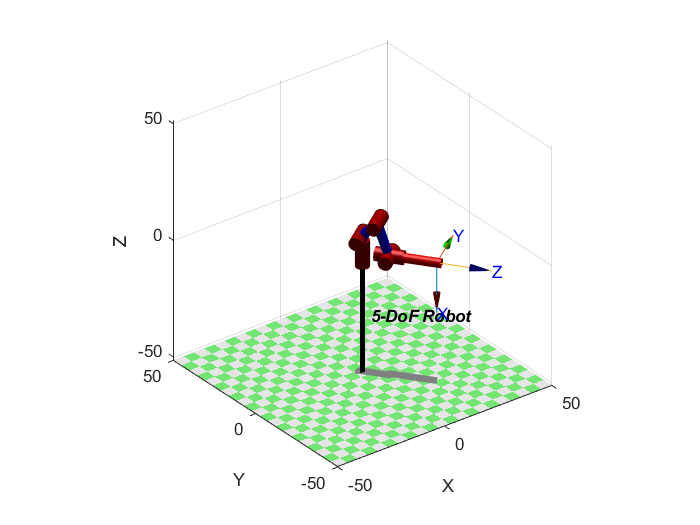



% Provide an initial guess (q0) closer to the desired over-arm configuration
%q0 = [-pi/8, -pi/182, -pi/175, -pi/2, 0]; % Example joint angles for over-arm
%q0 = [-pi/8, -pi/3, pi/9, pi/20, 0]; % Example1 for 32.5,-7.5,2
%q0 = [-pi/8, -pi/3, pi/6, -pi/18, 0]; %exampe 2 for 37.5, -12.5,2
q0 = [-pi/9, -pi/18, -pi/10, -pi/180, 0]; %exampe 3 for 27.5, -7.5,2

%q0 = [pi/2, pi/2, pi/2, pi/2, pi/2];

% Solve for IK with the mask and initial guess
q = robot.ikine(target_pose, 'mask', [1 1 1 0 1 1], 'q0', q0);


% Check for IK success
if ~isempty(q)
    % Plot the resulting configuration
    robot.plot(q);
else
    error('Inverse kinematics failed. Try adjusting the initial guess or target position.');
end


% Display the result
disp('Computed joint angles:');

Computed joint angles:


disp(q);

   -0.9448   -0.7411   -0.5138    0.5218    0.0000



extra

% Desired position (x, y, z)
position = [0.5, 0.3, 0.6]; % Target position in meters

% Desired orientation (rotation matrix)
orientation = rpy2tr(0, pi/2, pi/4); % Roll, pitch, yaw to rotation matrix

% Combine position and orientation into a homogeneous transformation matrix
target_pose = transl(position) * orientation;
disp(target_pose);

         0   -0.7071    0.7071    0.5000
         0    0.7071    0.7071    0.3000
   -1.0000         0         0    0.6000
         0         0         0    1.0000



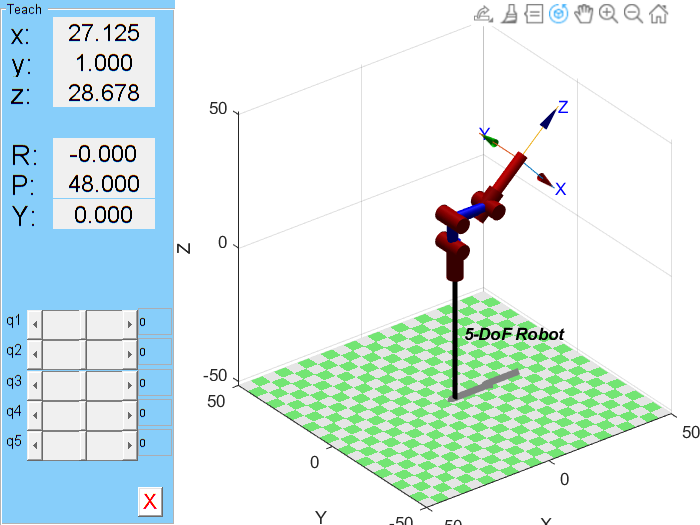

% Visualize
robot.teach(); % Interactive GUI for visualizing robot movements